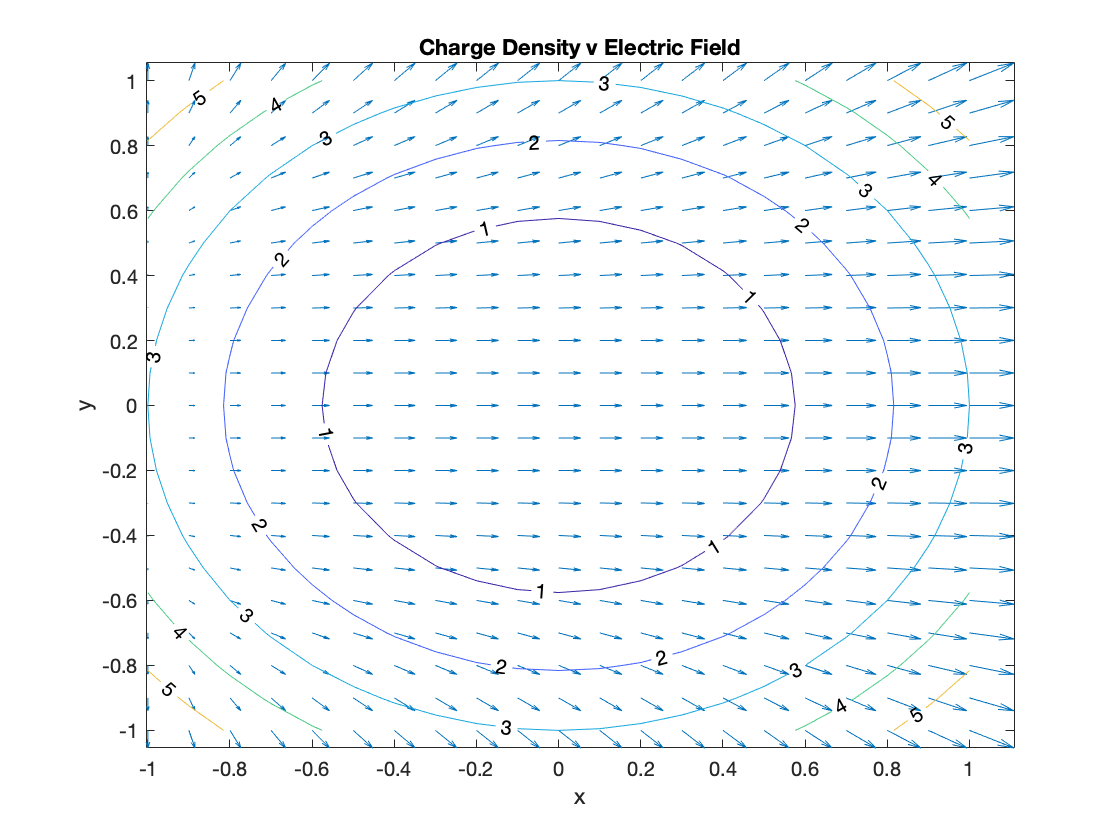

syms x y epesilon0
E = [x^3+1 y^3];
chargedensity= epesilon0*divergence(E,[x y]);
chargedensity = subs(chargedensity,epesilon0,1);
v = -1:0.1:1;
[xcontour,ycontour] = meshgrid(v);
    Ex = subs(E(1),x,xcontour);
    Ey = subs(E(2),y,ycontour);
densityPlot = subs(chargedensity,{x,y},{xcontour,ycontour});
quiver(xcontour,ycontour,Ex,Ey)
hold on
contour(xcontour,ycontour,densityPlot,'ShowText','on')
title('Charge Density v Electric Field')
xlabel('x')
ylabel('y')

v0 = [5 0 0];  %initial velocity 
E = [x^3+1 y^3 0];
m = 5;
q = 2; 
r0 = [0 0];
tspan = [0 100];
y0 = [r0; v0];

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

force = q*(cross(v0,E))
